# 3. (30%) A flat aluminum bar has constant thickness of 10 mm and a variable symmetric profile as shown in the figure below.

clc; clear; close all;

## (a) Construct the Lagrange interpolation functions.

syms x;

xe = [0 15 30 45 60 75 90];

N = sym(ones(7, 1));

for i = 1 : length(N)
    xj = (xe(xe ~= xe(i)));
    N(i, 1) = simplify(prod((x - xj) ./ (xe(i) - xj)));
end

thickness = 10; % mm
Ae = thickness * [8 10 9 12 12 10 5];

A(x) = simplify(Ae * N)

$$A(x) = -\frac{4\,x^{6}}{102515625}+\frac{17\,x^{5}}{1518750}-\frac{223\,x^{4}}{182250}+\frac{253\,x^{3}}{4050}-\frac{5897\,x^{2}}{4050}+\frac{572\,x}{45}+80$$

## (b) Use the Lagrange interpolation functions given in (a) and determine the half-area function. Graph the interpolation with a MATLAB plot. The interpolation function should pass through all the seven data points. A sample MATLAB plot is given below.

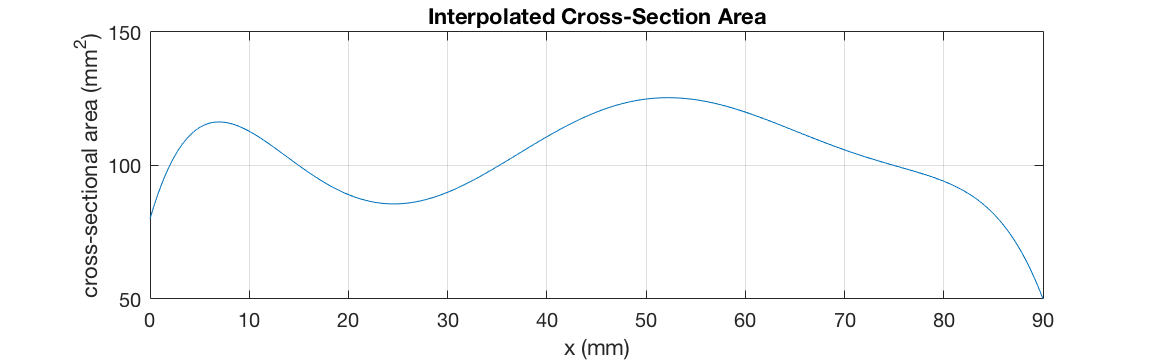

t = 0 : 0.1 : 90;

figure;
plot(t, A(t));
title('Interpolated Cross-Section Area');
xlabel('x (mm)');
ylabel('cross-sectional area (mm^2)');
yticks([50 100 150]);
axis([0 90 50 150]);
set(gcf, 'units', 'normalized', 'position', [0, 0, 0.4, 0.2]);
grid on;

## (c) Use the Lagrange interpolation functions given in (a) and determine the interpolation function for its profile. Graph the interpolation with a MATLAB plot. The interpolation function should pass through all the seven data points. A sample MATLAB plot is given below.

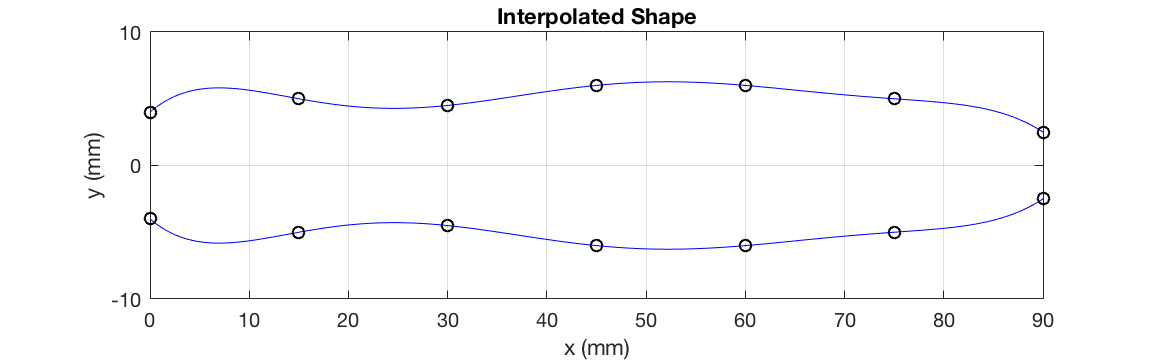

y = A(t) / thickness / 2;
ye = Ae / thickness / 2;

figure;
plot(t, y,'b', t, - y, 'b', xe, ye, 'ko', xe, - ye, 'ko');
title('Interpolated Shape');
xlabel('x (mm)');
ylabel('y (mm)');
axis([0 90 -10 10]);
yticks([-10 0 10]);
set(gcf, 'units', 'normalized', 'position', [0, 0, 0.4, 0.2]);
grid on;